%opens multiple files and plots data

%Gets number of .mat files in directory
cd 'C:\Users\serva\OneDrive\Documents\School Stuff\Senior year 1 Sp\BIOM 431\Group_Project'
matFiles = dir('*.mat');
numfiles = length(matFiles);
mydata = cell(1, numfiles);

%Constants for data we are using 
N = 3000000; %num of samples
dt = 1/5000;  
t = ((1:N)-1)*dt; %time vector


fn = 1×1 cell array
    {'interictal_segment_1'}


x =    122   122   122   122   124   126   127   127   127   127   126   127   127   127   128   128   129   130   129   129   129   130   131   132   132   131   131   130   130   129   129   128   127   128   128   128   128   128   128   128   128   128   126   125   125   124   123   122   121   122


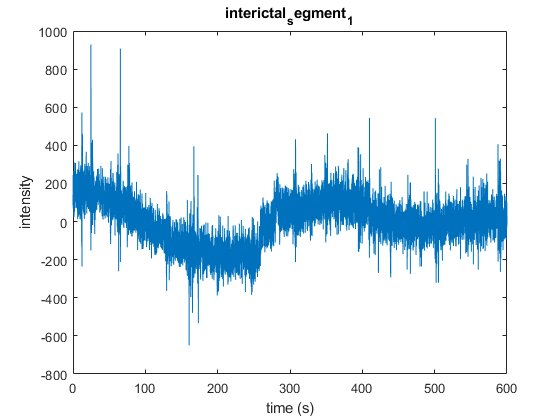

fn = 1×1 cell array
    {'interictal_segment_2'}


x =   -220  -219  -218  -217  -216  -216  -216  -216  -217  -217  -216  -215  -212  -211  -212  -213  -215  -215  -216  -217  -218  -219  -219  -219  -219  -220  -221  -220  -220  -220  -221  -222  -222  -221  -220  -220  -221  -223  -224  -223  -223  -224  -225  -225  -225  -225  -225  -226  -227  -228


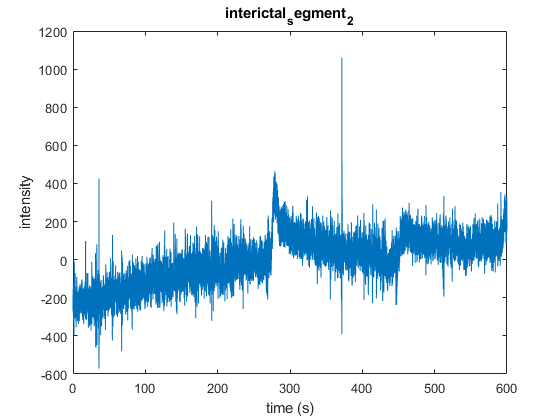

fn = 1×1 cell array
    {'interictal_segment_3'}


x =     68    68    68    68    67    67    67    67    68    69    69    68    68    69    69    69    69    69    70    70    70    69    68    67    67    67    67    67    67    68    69    70    71    71    71    72    73    76    77    78    79    80    84    85    86    86    87    89    90    90


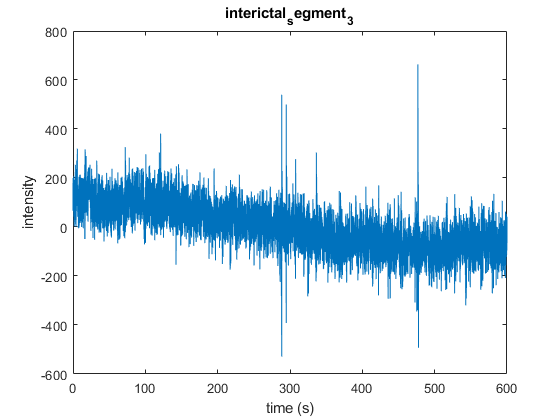

fn = 1×1 cell array
    {'interictal_segment_4'}


x =   -121  -121  -120  -120  -120  -121  -121  -121  -120  -119  -119  -118  -118  -117  -117  -118  -118  -119  -120  -119  -119  -120  -121  -122  -122  -122  -122  -121  -121  -121  -121  -121  -122  -123  -123  -123  -123  -123  -123  -122  -121  -120  -120  -121  -121  -121  -121  -121  -121  -121


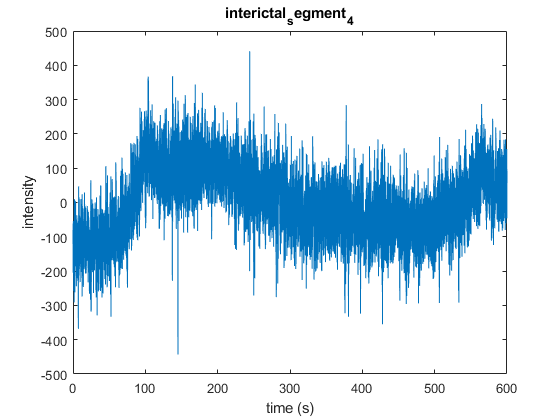

fn = 1×1 cell array
    {'interictal_segment_5'}


x =    423   424   426   427   428   429   429   429   428   429   430   432   434   435   434   433   433   432   433   435   436   437   438   439   439   440   440   441   443   445   444   443   442   443   445   446   446   444   444   445   447   448   449   449   450   452   452   452   451   451


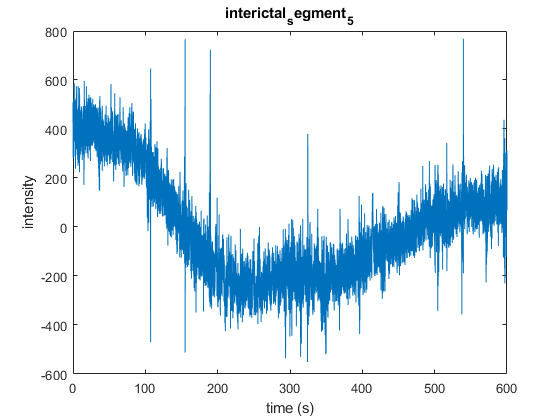

fn = 1×1 cell array
    {'interictal_segment_6'}


x =   -174  -174  -175  -176  -176  -177  -177  -178  -178  -178  -177  -176  -177  -178  -179  -179  -179  -179  -180  -182  -182  -181  -180  -180  -182  -183  -183  -183  -181  -181  -180  -180  -180  -180  -181  -181  -181  -180  -179  -179  -180  -181  -180  -180  -180  -181  -182  -182  -181  -179


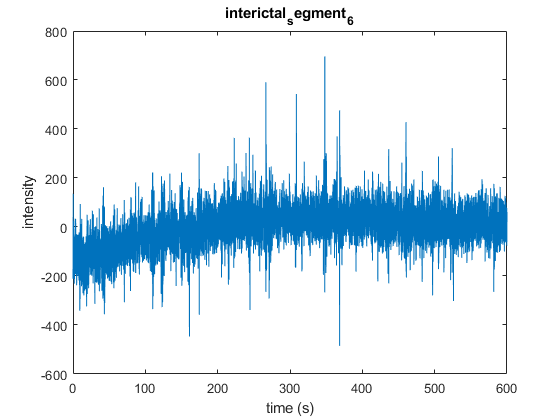

fn = 1×1 cell array
    {'preictal_segment_1'}


x =        40814       39730       38218       37225       36047       35190       34258       32777       31346       28403       25226       21339       15904       12615        9637        8199        6881        4789        3002         191       -2509       -6068      -12018      -16271      -20203      -21512      -22280      -24426      -27520      -32781      -36040      -38017      -38987      -39380      -40465      -41555      -42440      -42836      -42610      -41962      -41312      -40446      -38890      -37610      -35955      -34840      -33774      -32418      -31528      -30257


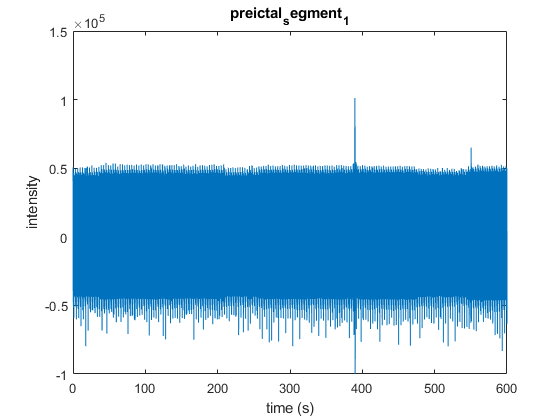

%Opens each .mat file and plots results add stuff you want to do to data
%here
for k = 1:numfiles
   mydata{k} = load(matFiles(k).name);
   fn = fieldnames(mydata{k})
   x = mydata{1,k}.(fn{1}).data(1,:) % x is equal to the data
   figure
   plot(t,x)
   xlabel('time (s)')
   ylabel('intensity')
   title(fn{1})
end